# **Ch8 Image segmentation**

## **Global threshold 1**

im_input = rgb2gray(imread('.\Pics\Ch10\noisy_fingerprint.jpg'));
figure,imshow(im_input),title('原图');
figure, imhist(im_input),title('原图的直方图');
count = 0; 
T = mean2(im_input); 
done = false;          
while ~done 
      count = count + 1; 
      g = im_input > T; 
      Tnext = 0.5*(mean(im_input(g)) + mean(im_input(~g))); 
      done = abs(T - Tnext) < 0.5; 
      T = Tnext; 
end 

count
T

im_output = im2bw(im_input, T/255); 
figure,imshow(im_output);title('阈值化结果');
imwrite(im_output, '1.jpg');

## **Global threshold 2**

im_input = imread('.\Pics\Ch10\polymersomes.tif');
figure,imshow(im_input),title('原图');
figure, imhist(im_input),title('原图的直方图');
count = 0; 
T = mean2(im_input); 
done = false;          
while ~done 
      count = count + 1; 
      g = im_input > T; 
      Tnext = 0.5*(mean(im_input(g)) + mean(im_input(~g))); 
      done = abs(T - Tnext) < 0.5; 
      T = Tnext; 
end 

count
T

im_output = im2bw(im_input, T/255); 
figure,imshow(im_output);title('阈值化结果');
% imwrite(im_output, '1.jpg');

## **Otsu method**

im_input = imread('.\Pics\Ch10\polymersomes.tif');
figure,imshow(im_input),title('原图');

T = graythresh(im_input);
T*255
im_output = im2bw(im_input, T); 
figure,imshow(im_output);title('Otsu阈值化结果');

## **Otsu method with smooting filter 1**

im_input = imread('.\Pics\Ch10\septagon.tif');
figure,imshow(im_input),title('原图');
% figure, imhist(im_input),title('原图的直方图');

T1 = graythresh(im_input);
T1*255
im_output1 = im2bw(im_input, T1); 
figure,imshow(im_output1);title('Otsu阈值化结果：原始图像');

im_noise = imnoise(im_input,'gaussian',0,0.05);
figure,imshow(im_noise),title('含噪图像');
figure, imhist(im_noise),title('含噪图像的直方图');
T2 = graythresh(im_noise);
T2*255
im_output2 = im2bw(im_noise, T2); 
figure,imshow(im_output2);title('Otsu阈值化结果：含噪图像');

h = fspecial('average',[5 5]);
im_smooting = imfilter(im_noise,h);
figure,imshow(im_smooting),title('含噪图像平滑处理');
figure, imhist(im_smooting),title('含噪图像平滑处理后的直方图');
T3 = graythresh(im_smooting);
T3*255
im_output3 = im2bw(im_smooting, T3); 
figure,imshow(im_output3);title('Otsu阈值化结果：含噪图像平滑处理');

## **Otsu method with smooting filter **

im_input = imread('.\Pics\Ch10\septagon_noise.tif');
figure,imshow(im_input),title('原图');
figure, imhist(im_input),title('原图的直方图');

T1 = graythresh(im_input);
T1*255
im_output1 = im2bw(im_input, T1); 
figure,imshow(im_output1);title('Otsu阈值化结果：原始图像');

h = fspecial('average',[5 5]);
im_smooting = imfilter(im_input,h);
figure,imshow(im_smooting),title('平滑处理图像');
figure, imhist(im_smooting),title('平滑处理后的直方图');
T2 = graythresh(im_smooting);
T2*255
im_output2 = im2bw(im_smooting, T2); 
figure,imshow(im_output2);title('Otsu阈值化结果：平滑处理');

## **Threshold-based segmentation using OTSU method, smooting filter and gradient 1**

f = im2double(imread('.\Pics\Ch10\septagon_noise.tif'));
figure,imshow(f),title('原图');
figure, imhist(f),title('原图的直方图');

sx = fspecial('sobel'); 
sy = sx'; 
gx = imfilter(f,sx,'replicate'); 
gy = imfilter(f,sy,'replicate'); 
grad = sqrt(gx.*gx + gy.*gy); 
grad = grad/max(grad(:)); 
h = imhist(grad); 
Q = percentile2i(h, 0.999); 
markerImage = grad > Q; 
figure, imshow(markerImage),title('二值模板图');

fp = f.*markerImage; 
figure, imshow(fp),title('处理图像'); 
hp = imhist(fp);
hp(1) = 0;  % 为了显示方便
figure, bar(hp),title('处理后的直方图');

T = graythresh(hp);
g = im2bw(f, T); 
figure, imshow(g) ,title('最终二值化结果');

## **Threshold-based segmentation using OTSU method, smooting filter and gradient 2**

f = im2double(imread('.\Pics\Ch10\yeast.tif'));
figure,imshow(f),title('原图');
figure, imhist(f),title('原图的直方图'); 
[Tf SMf] = graythresh(f); 
gf = im2bw(f, Tf);
figure, imshow(gf),title('OTSU分割结果'); 

 w = [-1 -1 -1; -1 8 -1; -1 -1 -1]; 
lap = abs(imfilter(f, w, 'replicate')); 
lap = lap/max(lap(:)); 
h = imhist(lap); 
Q = percentile2i(h, 0.995); 
markerImage = lap > Q; 
fp = f.*markerImage; 
figure, imshow(fp) ,title('标记图像'); 
hp = imhist(fp);
hp(1) = 0;  % 为了显示方便
figure, bar(hp),title('处理后的直方图');

T = graythresh(hp); 
g = im2bw(f, T); 
figure, imshow(g),title('最终二值化结果');

## Variable threshold method 1

f = im2double(imread('.\Pics\Ch10\yeast.tif'));
figure,imshow(f),title('原图');
TGlobal = multithresh(f,2); 
gGlobal = imquantize(f,TGlobal); 
imshow(gGlobal,[]), title('双阈值分割结果');
g = localthresh(tofloat(f), ones(3), 30, 1.5, 'global'); 
SIG = stdfilt(f, ones(3)); 

figure, imshow(SIG, [ ]), title('标准差图'); 
figure, imshow(g), title('可变阈值分割结果');  

## Variable threshold method 2

im_input = im2double(imread('.\Pics\Ch10\spot_shaded_text.tif'));
figure, imshow(im_input),title('input image');

T = graythresh(im_input); 
g1 = im2bw(im_input, T);
figure, imshow(g1),title('Otsu法分割结果');

g2 = movingthresh(im_input, 20, 0.5); 
figure, imshow(g2), title('移动平均法分割结果'); 

## Variable threshold method 3

im_input = im2double(imread('.\Pics\Ch10\sine_shaded_text.tif'));
figure, imshow(im_input),title('input image');

T = graythresh(im_input); 
g1 = im2bw(im_input, T);
figure, imshow(g1),title('Otsu法分割结果');

g2 = movingthresh(im_input, 20, 0.5); 
figure, imshow(g2), title('移动平均法分割结果'); 

## Point detection

im_input = im2double(imread('.\Pics\Ch10\wirebond.tif'));
figure, imshow(im_input),title('input image');

H = [-1 -1 -1; -1 8 -1; -1 -1 -1];

im_filter = abs(imfilter(im_input,H));

im_output = imbinarize(im_filter,0.9*max(im_filter(:)));

figure;imshow(im_output),title('point detection result');

## Line detection

im_input = im2double(imread('.\Pics\Ch10\wirebond.tif'));
figure, imshow(im_input),title('input image');

H=[-1 -1 -1; -1 8 -1; -1 -1 -1];

im_output =  imfilter(im_input, H);
im_bw = (im_output >=0);

figure;imshow(im_output,[]),title('标定');
figure;imshow(abs(im_output)),title('绝对值');
figure;imshow(im_output.*im_bw),title('只取正值');

## Sobel operator

im_input = im2double(imread('.\Pics\Ch10\building.tif'));
im_input = imresize(im_input,0.5);
figure, imshow(im_input); title('input image');
H1=[ -1 -2 -1;0 0 0;1 2 1];
H2=H1';

im_output = im_input;
% H = fspecial('average', [5 5]);
% im_output =  imfilter(im_input, H);
% figure, imshow(im_output); title('after smooting');

im_grad_x = imfilter(im_output,H1);
im_grad_y = imfilter(im_output,H2);
im_grad = abs(im_grad_x)+abs(im_grad_x);
im_edge1 = im_grad > 0.2*max(im_grad(:));
im_edge2 = im_grad > 0.33*max(im_grad(:));

figure;imshow(abs(im_grad_x),[]),title('|gx|');
figure;imshow(abs(im_grad_y),[]),title('|gy|');
figure;imshow(im_grad,[]),title('|gx|+|gy|');
figure;imshow(im_edge1),title('edge map: using low threshold');
figure;imshow(im_edge2),title('edge map: using high threshold');

## Edge detection using gradient operator: comparison

im_input = im2double(imread('.\Pics\Ch10\building.tif'));
im_input = imresize(im_input,0.5);
figure, imshow(im_input); title('input image');

im_edge_roberts = edge(im_input,'Roberts');
im_edge_prewitt = edge(im_input,'Prewitt');
im_edge_sobel = edge(im_input,'Sobel');

figure;imshow(im_edge_roberts),title('edge map: using roberts operator');
figure;imshow(im_edge_prewitt),title('edge map: using prewitt operator');
figure;imshow(im_edge_sobel),title('edge map: using sobel operator');

## LoG operator

im_input = im2double(imread('.\Pics\Ch10\building.tif'));
% im_input = imresize(im_input,0.5);
figure, imshow(im_input); title('input image');

G = fspecial('gaussian', 25,4);
im_gaussian = imfilter(im_input, G);
H1 = [1 1 1; 1 -8 1; 1 1 1];
im_log = imfilter(im_gaussian, H1);

im_edge1 = edge(im_log,'zerocross', 0);
thre1 = 0.005*max(im_log(:))
im_edge2 = edge(im_log,'zerocross',thre1);

im_edge3 = edge(im_input,'log');

% figure;imshow(im_edge_roberts),title('edge map: using roberts operator');
figure;imshow(im_log,[]),title('LoG image');
figure;imshow(im_edge1),title('LoG+zerocross with th=0');
figure;imshow(im_edge2),title('LoG+zerocross with th=0.005*max');
figure;imshow(im_edge3),title('edge map: using LoG with system');
imwrite(im_edge1,'log.jpg');

## Hough transform 1

f = zeros(101, 101); 
f(1, 1) = 1; f(101, 1) = 1; f(1, 101) = 1; 
f(101, 101) = 1; f(51, 51) = 1;
[H, theta, rho] = hough(f); 
imshow(H, [], 'XData', theta, 'YData', rho ,'InitialMagnification', 'fit') 
axis on, axis normal 
xlabel('\theta'), ylabel('\rho') 

## Hough transform 2

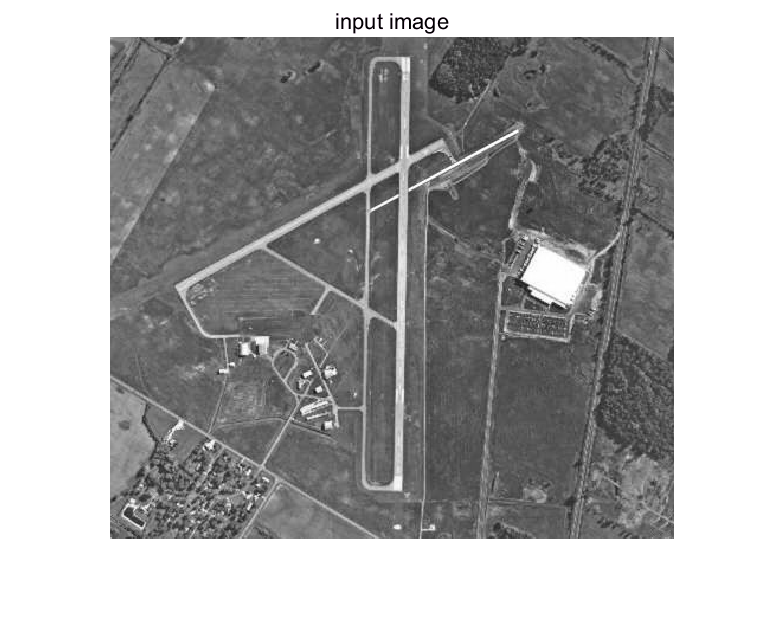

im_input = im2double(imread('.\Pics\Ch10\airport.tif'));
figure, imshow(im_input); title('input image');

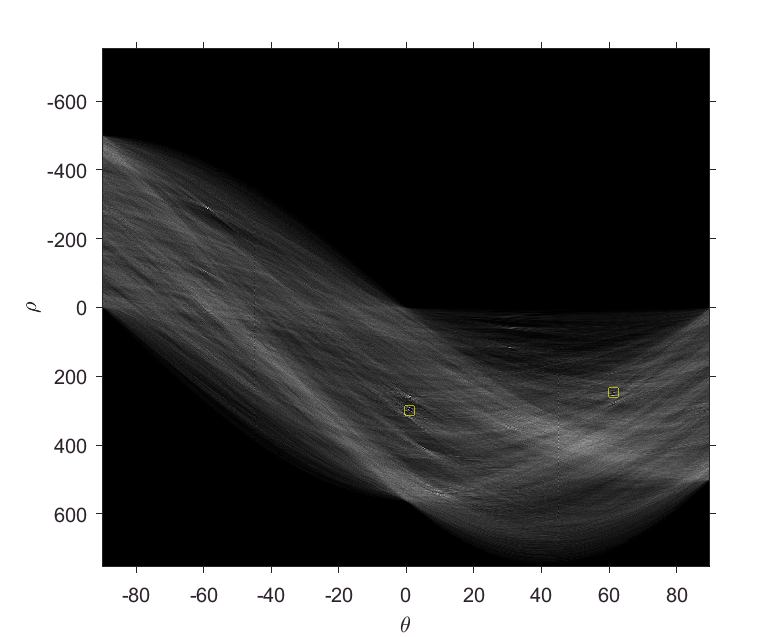

f=edge(im_input,'canny');

[H, theta, rho] = hough(f, 'ThetaResolution', 0.2); 
 imshow(H, [], 'XData', theta, 'YData', rho, 'InitialMagnification', 'fit') 
axis on, axis normal 
xlabel('\theta'), ylabel('\rho') 

peaks = houghpeaks(H, 2); 
hold on  
plot(theta(peaks(:, 2)), rho(peaks(:, 1)), 'linestyle', 'none', 'marker', 's', 'color', 'y') ;

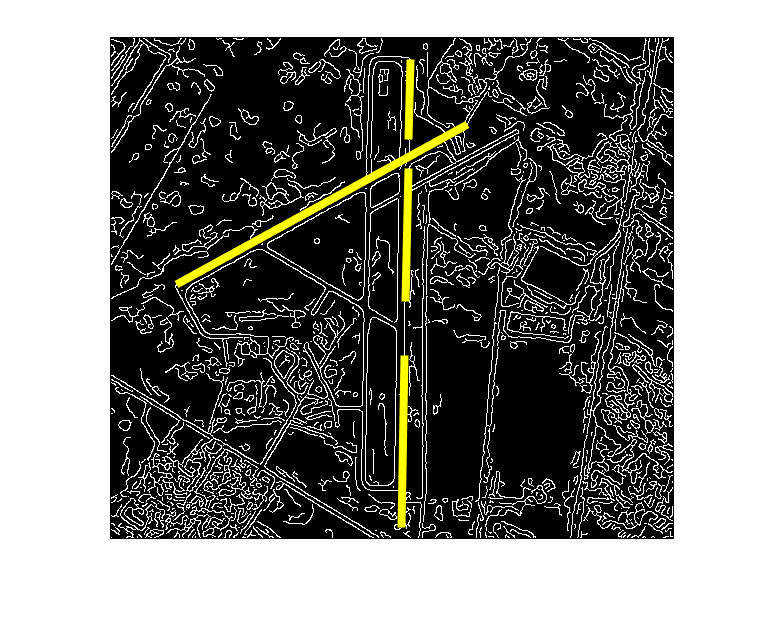

lines = houghlines(f, theta, rho, peaks); 
figure, imshow(f), hold on 
for k = 1:length(lines) 
xy = [lines(k).point1 ; lines(k).point2]; 
plot(xy(:,1), xy(:,2), 'LineWidth', 4, 'Color', [1 1 0]); 
end 

## Region growing

im_input = im2double(imread('.\Pics\Ch10\weld.tif'));
figure, imshow(im_input); title('input image');

[im_output, NR, SI, TI] = regiongrow(im_input, 1, 0.26); 

figure, imshow(im_output); title('region growing image');
figure, imshow(SI,[]); title('region growing image');
figure, imshow(TI); title('region growing image');

## Region split and merge

im_input = imread('.\Pics\Ch10\cygnusloop.tif');
figure, imshow(im_input); title('input image');

im_output1 = splitmerge(im_input, 32,  @predicate);
im_output2 = splitmerge(im_input, 16,  @predicate);
im_output3 = splitmerge(im_input, 8,  @predicate);
im_output4 = splitmerge(im_input, 4,  @predicate);
im_output5 = splitmerge(im_input, 2,  @predicate);

figure, imshow(im_output1,[]); title('segmentation result with dim=32');
figure, imshow(im_output2,[]); title('segmentation result with dim=16');
figure, imshow(im_output3,[]); title('segmentation result with dim=8');
figure, imshow(im_output4,[]); title('segmentation result with dim=4');
figure, imshow(im_output5,[]); title('segmentation result with dim=2');